path = "C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\26_01_10_Neurons\260129\260129\P003425\ActivityScan\000070\data.raw.h5";
%path ='C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\25_08_08_M231_PSD_PEDOT\PEDOT_Cells_72hr.raw.h5';
% path = 'C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\25_08_01_M231_PSD\72HrCells.raw.h5'
wellID = 1;


data = mxw.fileManager(path,wellID);

%data = cellsRawData_72hr

ctrlFreshMediaDataPath = 'C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\25_08_08_M231_PSD_PEDOT\PEDOT_Media_Fresh_Media.raw.h5';
cells72HrDataPath = 'C:\Users\rzr517\Large_Data_Files\MaxOne\Recordings\25_08_08_M231_PSD_PEDOT\PEDOT_Cells_72hr.raw.h5';

rawpath = '/recordings/rec0000/well000/groups/routed';
wellID = 1;


ctrlMediaRawData = mxw.fileManager(ctrlFreshMediaDataPath,wellID);

% cellsRawData_72hr = mxw.fileManager(cells72HrDataPath,wellID);

file = 16

file = 16

n_traces = 10;
startSample = 1,

startSample = 1

fs = data.fileObj(file).samplingFreq

fs = 20000

dataChunkSize = 10;


%[tracesBP, ~, electrodesArray] = data.extractBPFData(startSample,dataChunkSize*fs,'file',file);
[tracesRawRaw, ~, ~] = data.extractRawData(startSample,dataChunkSize*fs, 'file',file);
[tracesRawCtrl, ~, ~] = ctrlMediaRawData.extractRawData(startSample,dataChunkSize*fs, 'file',1);

% tracesRawCtrl(:,any(tracesRawCtrl == 0))=[];
% tracesRawRaw(:,any(tracesRawRaw == 0))=[];

% skews = zeros(1,44)
% for i=1:44
%     [tracesRawRaw, ~, ~] = cellsRawData_72hr.extractRawData(startSample,dataChunkSize*fs, 'file',i);
%     skews(i) = (sum(skewness(tracesRawRaw),"omitnan"));
% 
%     
% end
% 
% plot(skews)


[sos,g] = butter(1,[1 300]./(20000/2),"bandpass");
filteredTraces = filtfilt(sos,g,double(tracesRawRaw));
tracesRaw = filteredTraces;

[sos,g] = butter(1,[1 300]./(20000/2),"bandpass");
filteredTraces = filtfilt(sos,g,double(tracesRawCtrl));
tracesRawCtrl = filteredTraces;



[x, indMax] = maxk(max((tracesRaw)),n_traces);
[x, indMin] = mink(min((tracesRaw)),n_traces);
[x, indLow] = mink(min(abs(tracesRaw)),n_traces);
clf;



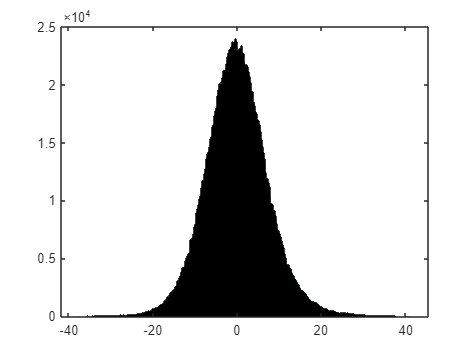

clf;
histogram(tracesRaw(:,indMax))


skewness(tracesRaw(:,indMax))

ans =     0.1008    0.1080    0.2176    0.5905    0.3035   -0.0148    0.0965    0.0856    0.4033    0.5785


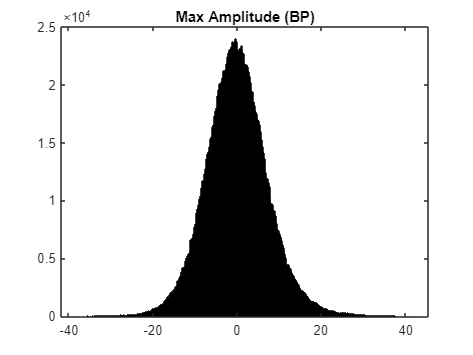

title('Max Amplitude (BP)')

histogram(tracesRaw(:,indMin))
skewness(tracesRaw(:,indMin))

ans =     0.1080   -0.2382    0.1008   -0.4557   -0.0187   -0.1103   -0.2837   -0.0943   -0.3307   -0.3440


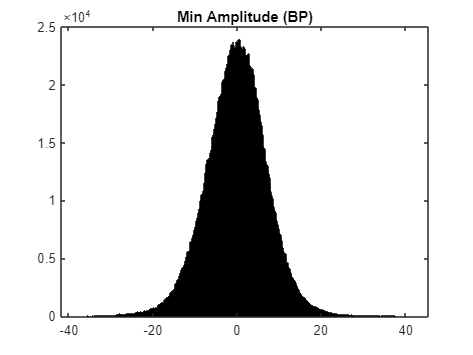

title('Min Amplitude (BP)')

histogram(tracesRaw(:,indLow))
skewness(tracesRaw(:,indLow))

ans =     0.0018   -0.0480    0.1650    0.0260   -0.0296   -0.0878    0.0171   -0.2837   -0.1180    0.0331


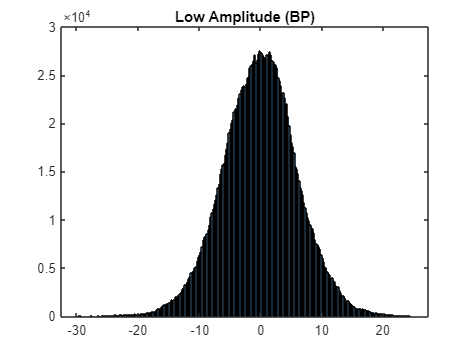

title('Low Amplitude (BP)')

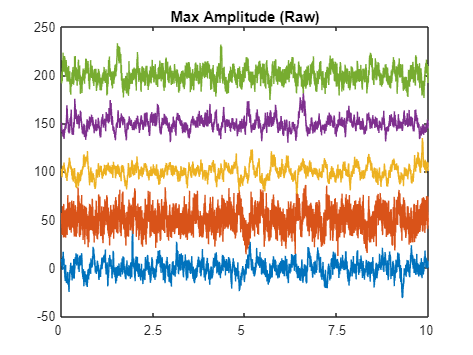





plot(tracesRaw(:,indMax(1)))
for i = 2:5

    hold on
    
    plot(tracesRaw(:,indMax(i))+((i-1)*50))

    hold off
end
title('Max Amplitude (Raw)')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

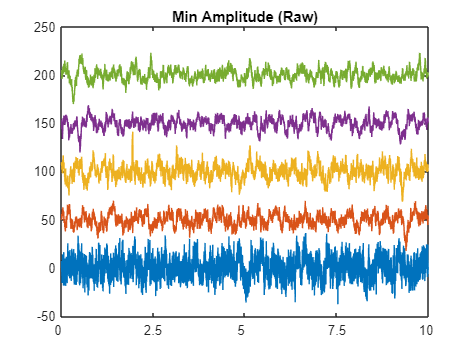





plot(tracesRaw(:,indMin(1)))
for i = 2:5

    hold on
    
    plot(tracesRaw(:,indMin(i))+((i-1)*50))

    hold off
end

title('Min Amplitude (Raw)')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

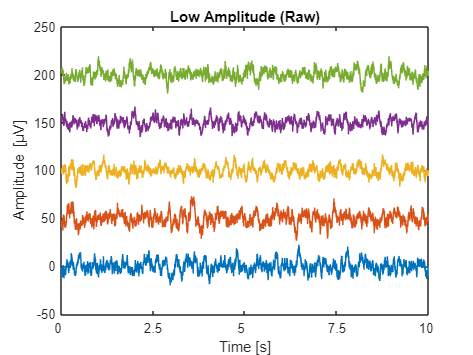



plot(tracesRaw(:,indLow(3)))
for i = 4:7

    hold on
    
    plot(tracesRaw(:,indLow(i))+((i-3)*50))

    hold off
end



title('Low Amplitude (Raw)')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;



xlabel('Time [s]')
ylabel('Amplitude [\muV]')

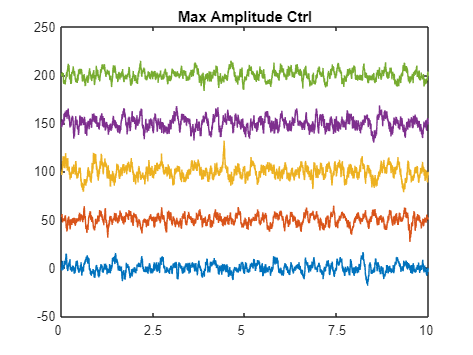




plot(tracesRawCtrl(:,indMax(1)))
for i = 2:5

    hold on
    
    plot(tracesRawCtrl(:,indMax(i))+((i-1)*50))

    hold off
end
title('Max Amplitude Ctrl')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

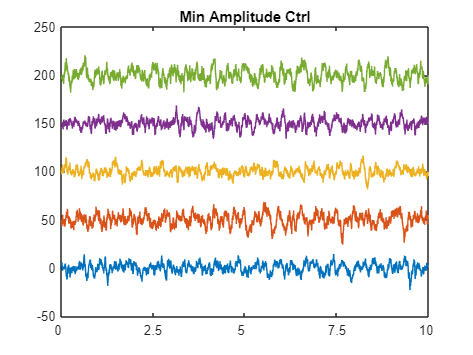





plot(tracesRawCtrl(:,indMin(1)))
for i = 2:5

    hold on
    
    plot(tracesRawCtrl(:,indMin(i))+((i-1)*50))

    hold off
end

title('Min Amplitude Ctrl')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

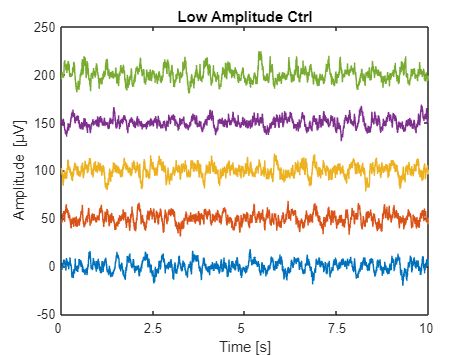



plot(tracesRawCtrl(:,indLow(3)))
for i = 4:7

    hold on
    
    plot(tracesRawCtrl(:,indLow(i))+((i-3)*50))

    hold off
end



title('Low Amplitude Ctrl')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;



xlabel('Time [s]')
ylabel('Amplitude [\muV]')

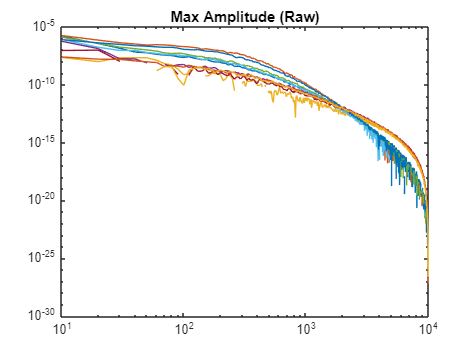

 overlap = 0;    
 nfft = (fs/10);
 window = hann(nfft);

 [PSD_SpikeMax,~] = pwelch(tracesRaw(:,indMax)/1000,window,overlap,nfft,fs);
 [PSD_SpikeMaxCtrl,~] = pwelch(tracesRawCtrl(:,indMax)/1000,window,overlap,nfft,fs);
 [PSD_SpikeMin,~] = pwelch(tracesRaw(:,indMin)/1000,window,overlap,nfft,fs);
 [PSD_SpikeMinCtrl,~] = pwelch(tracesRawCtrl(:,indMin)/1000,window,overlap,nfft,fs);

 [PSD_low,frequencies] = pwelch(tracesRaw(:,indLow)/1000,window,overlap,nfft,fs);
 [PSD_lowCtrl,~] = pwelch(tracesRawCtrl(:,indLow)/1000,window,overlap,nfft,fs);

 loglog(frequencies,(PSD_SpikeMax-PSD_SpikeMaxCtrl));
title('Max Amplitude (Raw)')

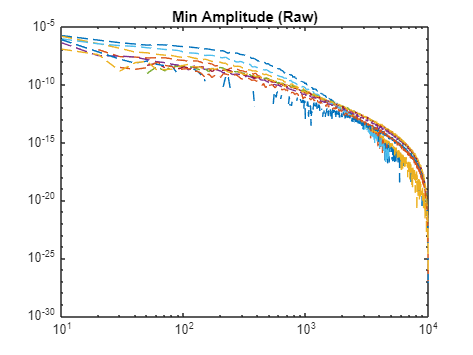


loglog(frequencies,(PSD_SpikeMin-PSD_SpikeMinCtrl),'LineStyle','--');
title('Min Amplitude (Raw)')


loglog(frequencies,(PSD_low-PSD_lowCtrl),'LineStyle','-');

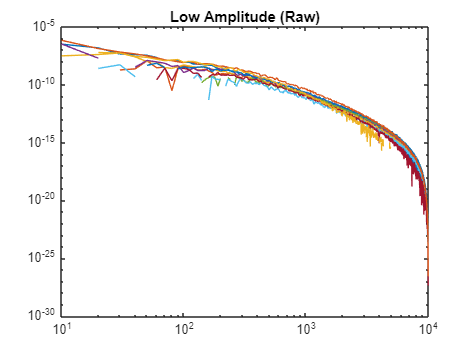

title('Low Amplitude (Raw)')

 overlap = 0;    

 nfft = (fs/dataChunkSize);
 window = hann(nfft);

colVars = skewness(tracesRaw, 0, 1);


[maxSkew, minIdx] = maxk(abs(colVars),n_traces);

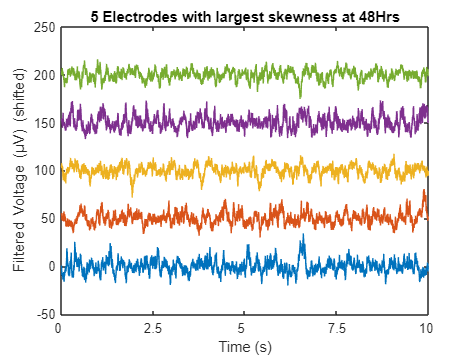

clf;
maxSkewnessVals = tracesRaw(:, minIdx);
maxSkewnessValsCtrl = tracesRawCtrl(:, minIdx);

plot(maxSkewnessVals(:,1))
for i = 2:5

    hold on
    plot(maxSkewnessVals(:,i)+((i-1)*50))

    hold off
end


title('5 Electrodes with largest skewness at 48Hrs')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

xlabel('Time (s)')
ylabel('Filtered Voltage (\muV) (shifted)')

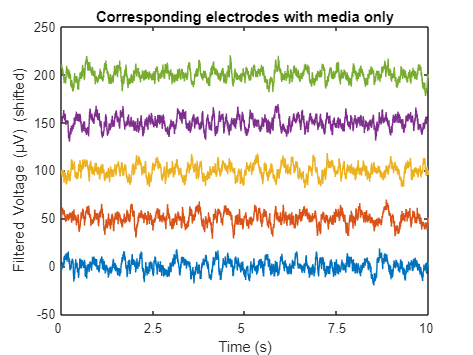


plot(maxSkewnessValsCtrl(:,1))
for i = 2:5

    hold on
    plot(maxSkewnessValsCtrl(:,i)+((i-1)*50))

    hold off
end

title('Corresponding electrodes with media only')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

xlabel('Time (s)')
ylabel('Filtered Voltage (\muV) (shifted)')


[PSD_maxSkew,frequencies] = pwelch(maxSkewnessVals/1000,window,overlap,nfft,fs);
[PSD_maxSkewCtrl,frequencies] = pwelch(maxSkewnessValsCtrl/1000,window,overlap,nfft,fs);


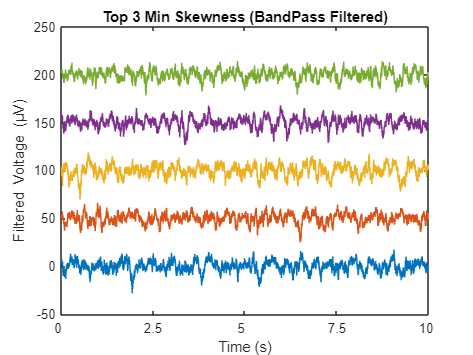


[minSkew, minIdx] = mink((colVars),n_traces);

minSkewnessVals = tracesRaw(:, minIdx);
minSkewnessValsCtrl = tracesRawCtrl(:, minIdx);
plot(minSkewnessVals(:,1))
for i = 2:5

    hold on
    plot(minSkewnessVals(:,i)+((i-1)*50))

    hold off
end

title('Top 3 Min Skewness (BandPass Filtered)')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

xlabel('Time (s)')
ylabel('Filtered Voltage (\muV)')

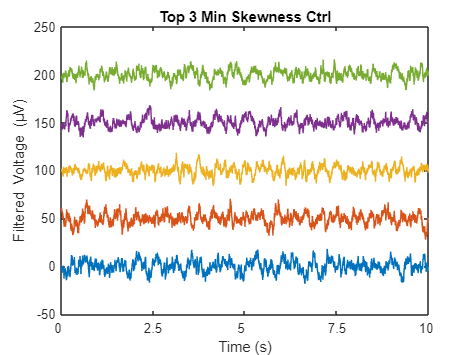


plot(minSkewnessValsCtrl(:,1))
for i = 2:5

    hold on
    plot(minSkewnessValsCtrl(:,i)+((i-1)*50))

    hold off
end

title('Top 3 Min Skewness Ctrl')
ax = gca;
tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

xlabel('Time (s)')
ylabel('Filtered Voltage (\muV)')


[PSD_minSkew,~] = pwelch(minSkewnessVals/1000,window,overlap,nfft,fs);
[PSD_minSkewCtrl,~] = pwelch(minSkewnessValsCtrl/1000,window,overlap,nfft,fs);

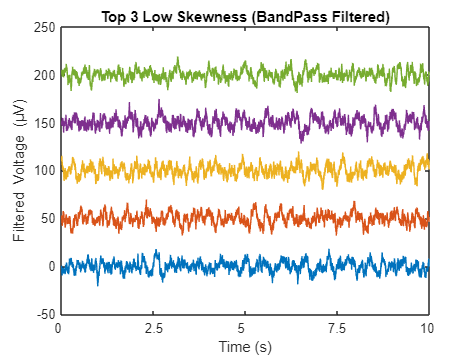



[lowSkew, minIdx] = mink(abs(colVars),n_traces);

lowSkewnessVals = tracesRaw(:, minIdx);
lowSkewnessValsCtrl = tracesRawCtrl(:, minIdx);

plot(lowSkewnessVals(:,1))
for i = 2:5

    hold on
    plot(lowSkewnessVals(:,i)+((i-1)*50))

    hold off
end


title('Top 3 Low Skewness (BandPass Filtered)')
ax = gca;

tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

xlabel('Time (s)')
ylabel('Filtered Voltage (\muV)')

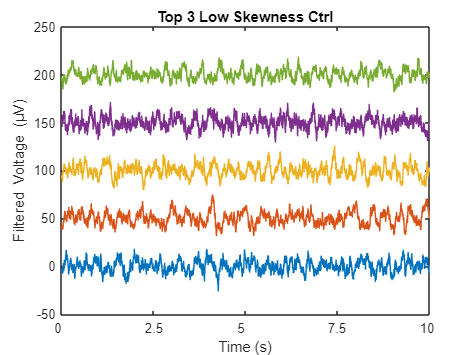



plot(lowSkewnessValsCtrl(:,1))
for i = 2:5

    hold on
    plot(lowSkewnessValsCtrl(:,i)+((i-1)*50))

    hold off
end


title('Top 3 Low Skewness Ctrl')
ax = gca;

tick_scale_factor = 20000;
ax.XTickLabel = ax.XTick ./ tick_scale_factor;

xlabel('Time (s)')
ylabel('Filtered Voltage (\muV)')


[PSD_lowSkew,~] = pwelch(lowSkewnessVals/1000,window,overlap,nfft,fs);
[PSD_lowSkewCtrl,~] = pwelch(lowSkewnessValsCtrl/1000,window,overlap,nfft,fs);


histogram(maxSkewnessVals(:,2))
skewness(maxSkewnessVals(:,:))

ans =     0.5905    0.5785   -0.4906    0.4827   -0.4568   -0.4557    0.4239    0.4237    0.4195    0.4183


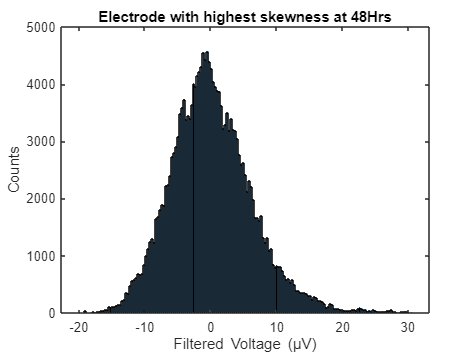

title('Electrode with highest skewness at 48Hrs')
ylabel('Counts')
xlabel('Filtered Voltage (\muV)')



histogram(maxSkewnessValsCtrl(:,2))
skewness(maxSkewnessValsCtrl(:,:))

ans =     0.0199   -0.2756   -0.0739   -0.0169   -0.0582   -0.0664   -0.3654    0.0763   -0.0467   -0.2882


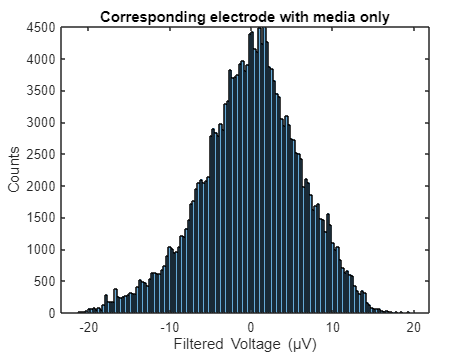

title('Corresponding electrode with media only')
ylabel('Counts')
xlabel('Filtered Voltage (\muV)')


histogram(minSkewnessVals(:,1:5))
skewness(minSkewnessVals(:,:))

ans =    -0.4906   -0.4568   -0.4557   -0.3993   -0.3988   -0.3879   -0.3876   -0.3849   -0.3798   -0.3723


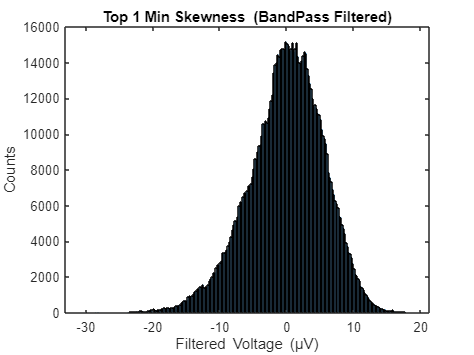

title('Top 1 Min Skewness  (BandPass Filtered)')
ylabel('Counts')
xlabel('Filtered Voltage (\muV)')

histogram(lowSkewnessVals(:,1:5))
skewness(lowSkewnessVals(:,:))

ans =     0.0006    0.0010    0.0014   -0.0014    0.0017   -0.0017    0.0018    0.0024   -0.0026   -0.0027


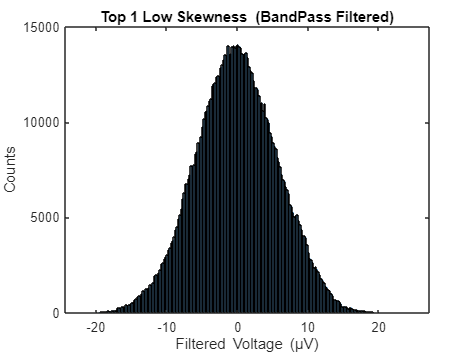

title('Top 1 Low Skewness  (BandPass Filtered)')
ylabel('Counts')
xlabel('Filtered Voltage (\muV)')

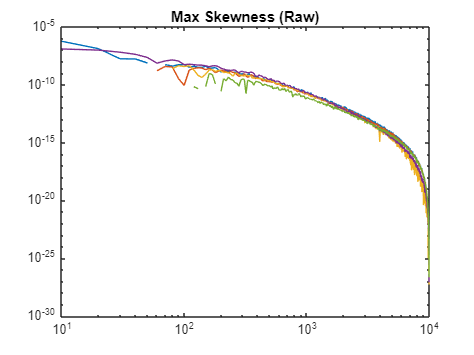

loglog(frequencies,(PSD_maxSkew(:,1:5)-PSD_maxSkewCtrl(:,1:5)));
title('Max Skewness (Raw)')


loglog(frequencies,(PSD_minSkew(:,1:5)-PSD_minSkewCtrl(:,1:5)),'LineStyle','--');

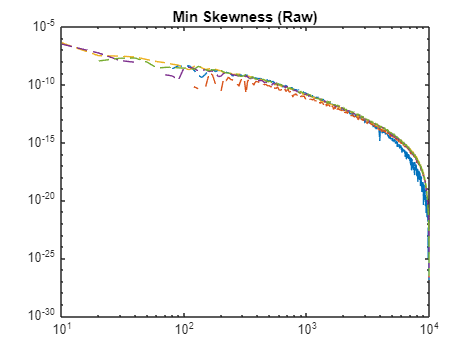

title('Min Skewness (Raw)')

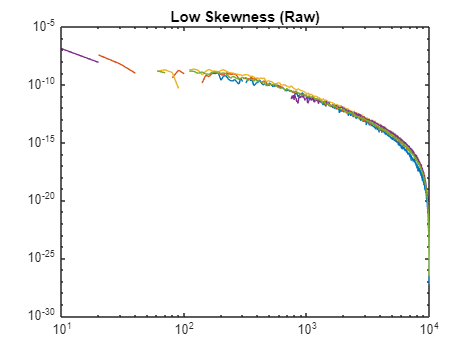

loglog(frequencies,(PSD_lowSkew(:,1:5)-PSD_lowSkewCtrl(:,1:5)),'LineStyle','-');
title('Low Skewness (Raw)')

avPSD = sum(PSD_maxSkew,2)/size(PSD_minSkew,2);

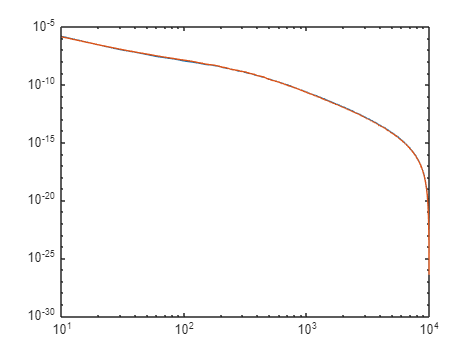


loglog(frequencies,(avPSD));

avPSD = sum(PSD_lowSkew,2)/size(PSD_lowSkew,2);
hold on
loglog(frequencies,(avPSD),'LineStyle','-');
hold off